# compare ssfr and stellar mass in profiles: 3d vs. projected. 

We generated 3d profiles as well as 3 projected profiles. We'll compare them to see whether the projection can explain the mis-match with observations. 

## Load in the 3d and projected profiles


global DEFAULT_MATFILE_DIR
global simDisplayName

fnameProj=[DEFAULT_MATFILE_DIR '/ssfr0_stellarMass_radProfiles_projected_yangSamplePoint_fiber_' simDisplayName];
load(fnameProj)
profFib=profStruct;

clear profStruct;


fnameProj=[DEFAULT_MATFILE_DIR '/ssfr0_stellarMass_radProfiles_projected_yangSamplePoint_' simDisplayName];
load(fnameProj)
prof=profStruct;

clear profStruct;

%fname3d=[DEFAULT_MATFILE_DIR '/ssfr0_stellarMass_radProfiles_' simDisplayName];

%load(fname3d);
%prof3d=profStruct;

%clear profStruct;

## add in the obs data


load([DEFAULT_MATFILE_DIR '/ssfr_rpos_dataGrab.mat'])

## plot all profiles

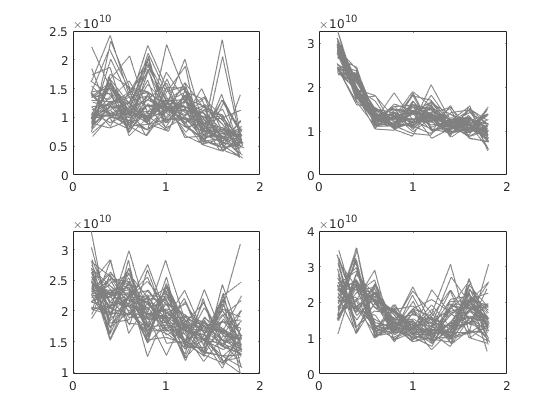

figure

for k=1:4

subplot(2,2,k)
for i=1:length(prof)
    
    plot(profFib(i).starMass(k).xMean,profFib(i).starMass(k).yMean,'color',[0.5 0.5 0.5],'LineWidth',0.5)
    hold on
    
end
end

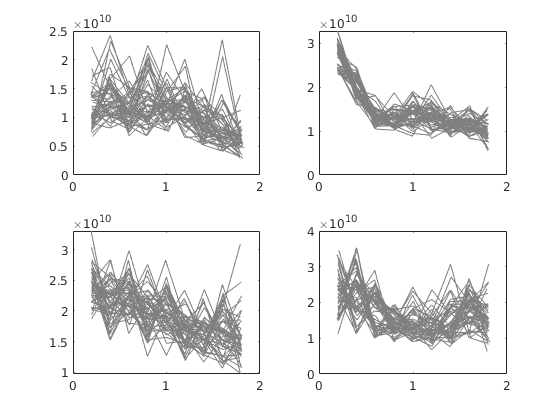



figure
for k=1:4

subplot(2,2,k)
for i=1:length(prof)
    
    plot(prof(i).starMass(k).xMean,prof(i).starMass(k).yMean,'color',[0.5 0.5 0.5],'LineWidth',0.5)
    hold on
    
end
end

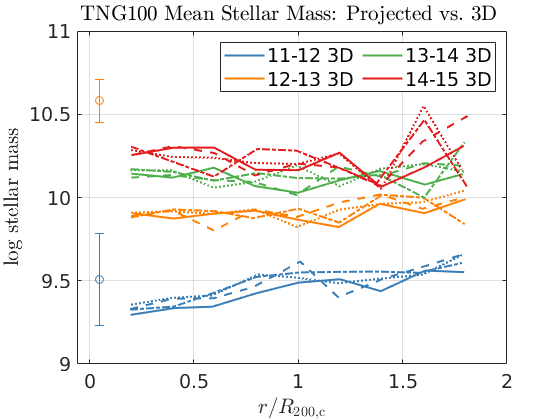






global DEFAULT_PRINTOUT_DIR
outDir=[DEFAULT_PRINTOUT_DIR '/obsComp'];

cc=brewermap(8,'Set1');
lt={'--',':','-.'};
hf=figure('color','w');
h=[];


for i=1:4 % run over host masses.
    
    xx=prof3d.starMass(i).xMean;
    y=prof3d.starMass(i).yMean;
    y1=log10(y-0.5*prof3d.starMass(i).yStanDev);
    y2=log10(y+0.5*prof3d.starMass(i).yStanDev);
    yy=log10(prof3d.starMass(i).yMean);
    
    %         xx=prof3d(k).starMass(i).xMedian;
    %         %y=prof3d(k).starMass(i).yMedian;
    %         y1=log10(prof3d(k).starMass(i).yQuarts(2,:));
    %         y2=log10(prof3d(k).starMass(i).yQuarts(3,:));
    %         yy=log10(prof3d(k).starMass(i).yMedian);
    
    xc=0.05;
    yc=log10(prof3d.starMassC(i).yMedian);
    ycP=log10(prof3d.starMassC(i).yQuarts(2,:))-yc;
    ycN=yc-log10(prof3d.starMassC(i).yQuarts(2,:));
    
    switch i
        case 1
            colo=cc(2,:);
            nam='11-12';
        case 2
            colo=cc(5,:);
            nam='12-13';
            
        case 3
            colo=cc(3,:);
            nam='13-14';
            
        case 4
            colo=cc(1,:);
            nam='14-15';
            
    end
    
    h(i)=plot(xx,yy,'color',colo,'DisplayName',[nam ' 3D'],"LineStyle",'-','linewidth',1.5);
    hold on
    
    errorbar(xc,yc,ycN,ycP,'o','color',colo)
    
    % plot projected
    for k=1:3
        xxp=profProj(k).starMass(i).xMean;
        yp=profProj(k).starMass(i).yMean;
        y1p=log10(y-0.5*profProj(k).starMass(i).yStanDev);
        y2p=log10(y+0.5*profProj(k).starMass(i).yStanDev);
        yyp=log10(profProj(k).starMass(i).yMean);
        
        
        
        
        plot(xxp,yyp,'color',colo,'DisplayName',nam,"LineStyle",lt{k},'linewidth',1.5);
        
        
    end
    
end

grid
set(gca,'Fontsize',14)
%
hl=legend(h,'numcolumns',3,'location','northEast','fontsize',14);
xlim([-0.06 2])
ylim([9 11])
xlabelmine('$r/R_\mathrm{200,c}$');
ylabelmine('log stellar mass');
titlemine([simDisplayName ' Mean Stellar Mass: Projected vs.\@ 3D '] );
%
printout_fig(gcf,['mean_stellarMass_radProf_projected' simDisplayName],'dir',outDir)

## sfr

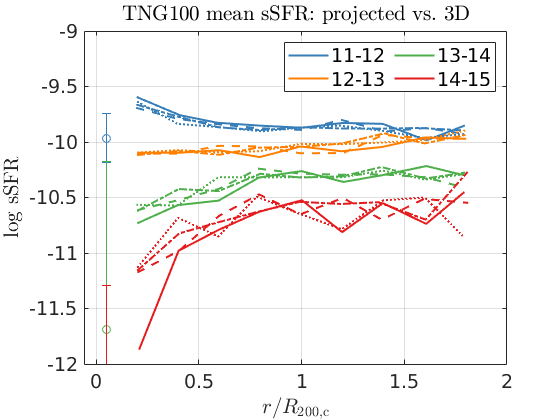

hf=figure('color','w');
h=[];

for i=1:4
    
            xx=prof3d.ssfrAvg(i).xMean;
            y=prof3d.ssfrAvg(i).yMean;
            y1=log10(y-0.5*prof3d.ssfrAvg(i).yStanDev);
            y2=log10(y+0.5*prof3d.ssfrAvg(i).yStanDev);
            yy=log10(prof3d.ssfrAvg(i).yMean);
    %
%     xx=prof3d(k).ssfrAvg(i).xMedian;
%     %y=prof3d(k).ssfrAvg(i).yMedian;
%     y1=log10(prof3d(k).ssfrAvg(i).yQuarts(2,:));
%     y2=log10(prof3d(k).ssfrAvg(i).yQuarts(3,:));
%     yy=log10(prof3d(k).ssfrAvg(i).yMedian);
%     
    xc=0.05;
    yc=log10(prof3d.ssfrAvgC(i).yMedian);
    ycP=log10(prof3d.ssfrAvgC(i).yQuarts(2,:))-yc;
    ycN=yc-log10(prof3d.ssfrAvgC(i).yQuarts(2,:));
    
    switch i
        case 1
            colo=cc(2,:);
            nam='11-12';
        case 2
            colo=cc(5,:);
            nam='12-13';
            
        case 3
            colo=cc(3,:);
            nam='13-14';
            
        case 4
            colo=cc(1,:);
            nam='14-15';
            
    end
    
    h(i)=plot(xx,yy,'-','color',colo,'DisplayName',nam,'linewidth',1.5);
        hold on
    
        
%         if k==1
%         
%         %errorbar(xx,yy,y1,y2,'color',colo)
%         patch([xx fliplr(xx)],[y1 fliplr(y2)],colo,...
%             'facealpha',0.1,'edgecolor','none')
%     elseif k==2 && i==1
%         
%         h(end+1)=plot(xx,yy,'color',colo,'DisplayName','TNG50-2',"LineStyle",lt);
%     elseif k==3 && i==1
%         h(end+1)=plot(xx,yy,'color',colo,'DisplayName','TNG50-3',"LineStyle",lt);
%     else
%         plot(xx,yy,'color',colo,'DisplayName',nam,"LineStyle",lt);
%         
%         
%     end
%     
    errorbar(xc,yc,ycN,ycP,'o','color',colo)
    
    for k=1:3
        
            xxP=profProj(k).ssfrAvg(i).xMean;
            yP=profProj(k).ssfrAvg(i).yMean;
            y1P=log10(y-0.5*profProj(k).ssfrAvg(i).yStanDev);
            y2P=log10(y+0.5*profProj(k).ssfrAvg(i).yStanDev);
            yyP=log10(profProj(k).ssfrAvg(i).yMean);
        
            plot(xxP,yyP,'color',colo,'DisplayName',nam,"LineStyle",lt{k},'linewidth',1.5);
        
        
    end
    
    
end

% for i=5:8
%     
%     switch i
%         case 5
%             xx=ssfr_rpos_11_main(2,:);
%             yy=ssfr_rpos_11_main(1,:);
%             pos=ssfr_rpos_11_top(1,:)-ssfr_rpos_11_main(1,:);
%             neg=ssfr_rpos_11_main(1,:)-ssfr_rpos_11_bottom(1,:);
%             colo=cc(2,:);
%             nam='11-12, Obs';
%             
%             ccc=ssfr_rpos_11_central(1,2);
%             cp=ssfr_rpos_11_central(1,3)-ssfr_rpos_11_central(1,2);
%             cm=ssfr_rpos_11_central(1,2)-ssfr_rpos_11_central(1,1);
%         case 6
%             xx=ssfr_rpos_12_main(2,:);
%             yy=ssfr_rpos_12_main(1,:);
%             pos=ssfr_rpos_12_top(1,:)-ssfr_rpos_12_main(1,:);
%             neg=ssfr_rpos_12_main(1,:)-ssfr_rpos_12_bottom(1,:);
%             colo=cc(5,:);
%             nam='12-13, Obs';
%             
%             ccc=ssfr_rpos_12_central(1,2);
%             cp=ssfr_rpos_12_central(1,3)-ssfr_rpos_12_central(1,2);
%             cm=ssfr_rpos_12_central(1,2)-ssfr_rpos_12_central(1,1);
%             
%         case 7
%             xx=ssfr_rpos_13_main(2,:);
%             yy=ssfr_rpos_13_main(1,:);
%             pos=ssfr_rpos_13_top(1,:)-ssfr_rpos_13_main(1,:);
%             neg=ssfr_rpos_13_main(1,:)-ssfr_rpos_13_bottom(1,:);
%             colo=cc(3,:);
%             nam='13-14, Obs';
%             
%             ccc=ssfr_rpos_13_central(1,2);
%             cp=ssfr_rpos_13_central(1,3)-ssfr_rpos_13_central(1,2);
%             cm=ssfr_rpos_13_central(1,2)-ssfr_rpos_13_central(1,1);
%             
%         case 8
%             xx=ssfr_rpos_14_main(2,:);
%             yy=ssfr_rpos_14_main(1,:);
%             pos=ssfr_rpos_14_top(1,:)-ssfr_rpos_14_main(1,:);
%             neg=ssfr_rpos_14_main(1,:)-ssfr_rpos_14_bottom(1,:);
%             colo=cc(1,:);
%             nam='14-15, Obs';
%             
%             ccc=ssfr_rpos_14_central(1,2);
%             cp=ssfr_rpos_14_central(1,3)-ssfr_rpos_14_central(1,2);
%             cm=ssfr_rpos_14_central(1,2)-ssfr_rpos_14_central(1,1);
%             
%     end
%     
%     
%     
%     
%     h(i)=errorbar(xx,yy,neg,pos,'x--','color',colo,...
%         'DisplayName',nam);
%     
%     errorbar(0,ccc,cm,cp,'x','color',colo)
% end


set(gca,'Fontsize',14)
grid
hl=legend(h,'numcolumns',2,'location','northEast','fontsize',14);
 xlim([-0.06 2])
 ylim([-12 -9])
xlabelmine('$r/R_\mathrm{200,c}$');
ylabelmine('log sSFR');
titlemine([simDisplayName ' mean sSFR: projected vs.\@ 3D'] );

printout_fig(gcf,['mean_ssfr_radProf_projected' simDisplayName],'dir',outDir)

%printout_fig(gcf,'median_ssfr0_radProf_TNG50','dir',outDir)
%printout_fig(gcf,'median_ssfr_radProf')